## CE640 / OC512

## Week 6

### Parameter Estimation 

In this week's class, we are going to learn about how one 'fits' a model to some data. The mathematical model that you choose is up to you, of course. But, all models have 'parameters' in them. And so, we need to figure out how to find the 'best' parameters. Matlab has a lot of built in tools for easy models (say, a straight line). But, we can customize this approach to any model we would like.


clear all
close all
clc

## Block 1 - What is a Curve Fit?

Let's take a quick look at some data and let's fit a straight line to it. A straight line is a 'two parameter' model. There is a slope and an intercept. So, let us create some data that looks like a straight line, but has some noise in it.

x=0:1:10;
m=0.5; %slope
b=1; %intercept

%create data, adding in some noise
yo=m*x+b+2*(rand(size(x))-0.5);

figure(1)
plot(x,yo,'o');
axis([0 10 0 6]);

Ok, nice. So, now if I ask you to fit a straight line to this, how do you do it? Do you simply 'eyeball' it? 

Once you 'run' this section, try experimenting with the sliders below. Look at how the figure changes. Adjust the sliders until you get the 'best' fit according to your eye.

close all
%set the slope
slope = 1 
%set the intercept
intercept = -0.3
%let's plot the result.
plot(x,yo,'o');
axis([0 10 0 6]);
hold on
plot(x,x*slope+intercept,'r')

Ok, so that's pretty cool. But, having to 'eyeball' things is not really accurate. So, we can fit a straight line incredibly quickly with polyfit. Polyfit will return the fit parameters, and we can use these along with polyval to compute the y data corresponding to the straight line fit.

close all
figure(3)
plot(x,yo,'o'); %plot the original data.
axis([0 10 0 6]);

%matlab best fit
P=polyfit(x,yo,1)
hold on
%plot YOUR best fit (from sliders above)
plot(x,x*slope+intercept,'r')
%plot matlab best fit
plot(x,polyval(P,x),'g')
legend('original data','eyeball fit','BEST fit')
title(['Best fit parameters: m = ' num2str(P(1)) ', b = ' num2str(P(2))])

But, what in the world is going on?? How does Matlab do this? Well, it has to do with minimizing the square error of the model fit. Consider this. We have N observed data values...


$$y_{o1}, y_{o2}, \ldots, y_{oN}$$


Now, we create a model, and we will have N model estimates of our data


$$y_{m1}, y_{m2}, \ldots, y_{mN}$$


We define the `residual error' between the estimates and the observations as


$$S=\sum_{i=1}^{N}(y_{o}-y_{m})^{2}$$


And, in the case of a straight line, where our proposed model is $y_{m}=mx+b$, our error is


$$S=\sum_{i=1}^{N}(y_{o}-mx-b)^{2}$$


So, now the goal of a 'good' curve fit is to minimze this error, right! It'll never be zero, but we need to make it as small as possible. To minimize something, we take it's derivative and set it to zero. So, let us differentiate with respect to the slope m and set the result equal to zero.


$$\frac{\partial S}{\partial m}=\sum 2(y_{o}-mx-b)\frac{\partial}{\partial x}(y_{o}-mx -b)=0$$


This becomes


$$\sum 2(y_{o}-mx-b)(-x)=0$$


Or, even simpler:


$$0=\sum y_{o}x - \sum mx^{2}-\sum bx$$


If we do the same thing, but differentiate the error with respect to the other model parameter, the intercept b, we get


$$0=\sum y_{o} - \sum mx-\sum b$$


Now, this is pure linear algebra. We can express this in a matrix form as


$$\pmatrix{\sum x^{2} & \sum x \cr \sum x & N} \pmatrix{m \cr b}=\pmatrix{\sum y_{o}x \cr \sum y_{0}}
$$


And, Matlab is brilliant at doing matrix solutions. Let's try this with the code below.

close all
figure(4)
plot(x,yo,'o'); %original data
axis([0 10 0 6]);
hold on

%matlab best fit from polyfit
plot(x,polyval(P,x),'g')

%try least squares...let us build up the matrix A (left matrix in the above
%section)
A(1,1)=sum(x.*x);
A(2,1)=sum(x);
A(1,2)=sum(x);
A(2,2)=length(x);
%next, let us build up the vector B (the column vector on the right hand
%side of the equation above
B(1,1)=sum(yo.*x);
B(2,1)=sum(yo);

%solving this is as easy as the next line!
soln=A\B;
%let us pull out the values of m and b, and plot the result...
mlsq=soln(1);
blsq=soln(2);
ylsq=mlsq*x+blsq;
plot(x,ylsq,'kx')

legend('Raw Data','Matlab Fit','Least Squares')

You can see that the least squares approach that we took is EXACTLY the same as Matlab's polyfit. This is how curve fitting is done!

## Block 2 - Beyond Straight Lines

Ok, well with Matlab we can do more that fit straight lines. Below is an illustration of using polyfit

clear all
close all

%lets create a quadratic (parabola) and then add some noise.
intercept = 0.5;
slope = 1;
curvature = 3;
x = [0: 0.2: 2];        % independent data
noiseAmp = 0.5;         % for random number noise

%create the actual data...
yData=polyval([curvature slope intercept],x) + noiseAmp*randn(size(x));
figure(5)
plot(x, yData, '*')
xlabel('x')
ylabel('y')
title('Some data to which we wish to apply a model...')

%Let's fit a quadratic to this with polyval. Note the ,2 (3rd argument of
%function). That is how we specify a 2nd order polynomial
p=polyfit(x,yData,2);   %try a quadratic.

%plot this
hold on
%compute the model estimate (the quadratic curve fit) from the parameters
yEst=polyval(p,x);
plot(x,yEst,'r')

%what happens if we guess the model poorly? Try linear fit
p2=polyfit(x,yData,1);  %linear
yEstlinear=polyval(p2,x);
plot(x,yEstlinear,'g')
legend('Data','Quad fit','Lin fit')

So, you can see that it is up to US to figure out what a good model to try is...linear, quadratic, exponential, etc. By the way, we can access all sorts of useful information on the fit by using more variables on the left hand side of the polyfit call.

%you can get information on how good the fit is.
[p2,S]=polyfit(x,yData,1);
S
S.normr    %this is the root mean square error, which is a measure of the goodness of fit.
[p3,S]=polyfit(x,yData,2);
S    %note the lower root mean square error in this case (the quadratic)

## BLOCK 3 - The Fit Function

So, polyfit is super cool. But it only works for polynomial fits. What if you think your data follows a different type of behaviour? What if it is exponential? Or, logarithmic? Or, seems to be described by some other mathematical function? Well, with the fit function, you can fit the data to whatever functional form you want! Let us illustrate this with some data that follows a quadratic:

clear all
close all

intercept = 2.5;
slope = 1;
curvature = 3;
x = [0: 0.2: 2]';        % independent data
noiseAmp = 0.5;         % for random number noise

%create the actual data...
yData=polyval([curvature slope intercept],x) + noiseAmp*randn(size(x));
figure(6)
plot(x, yData, '*')
xlabel('x')
ylabel('y')
title('Some data to which we wish to apply a model...')
hold on

Now, I am going to use the fit function. If you type 'help fit' at the command prompt, you can see that there are many options for you to select from. We could just choose a second order polynomial again:

%let's again try a polynomial (quadratic) fit
F0= fit(x,yData,'poly2')    %this is how we choose quad fit
%you will see information written to the screen on the coefficients and
%confidence intervals on those coefficients.

%plot results
plot(x,F0(x),'r')    %F0 is now like a function

Now, this is getting a bit outside the scope of this class (take a stats class!), but because of the noise in our data, our 'fit' is uncertain. We can consider the 95% confidence bounds and plot a result where we show the 'envelope' of results, due to our uncertainty.

%With the confidence intervals we can plot confidence bounds.
p11=predint(F0,x,0.95,'observation','off');
figure(2)
plot(F0,x,yData);
hold on
plot(x,p11,'m--')
legend off
title('Example of curve fitting with fit function')

What if we wanted a different proposed model fit? One not given as an option with the fit function? As an example, say we wanted to force our quadratic model to go through the origin? This essentially eliminates the 'constant' term in a polynomial fit. Well, we can create a custom fit type

ft=fittype( @(a,b,x) a*x.^2+b*x); %note that there is no intercept in this proposed model (well...it is 0).
F1=fit(x,yData,ft)  %you may need to help by supplying guess for starting point
                    %for parameter values...
                    
figure(3); hold off
plot(x,yData,'*'); hold on
plot(F1,'r')  %note we are not plottin x vs y; we are plotting a 'fit' variable type
title('Curve fitting with a custom polynomial model fit')

## Block 4 - Fundamental Least Squares Search

Ok, so, there is another way to go about things. We can take a 'brute force' approach for manually searching all of parameter space to find the parameters that give the best fit. This is not very elegant. But, sometimes, this approach may be necessary. Let us again illustrate this by generating some noisy quadratic data.

clear all
close all

intercept = 2.5;
slope = 1;
curvature = 3;
x = [0: 0.2: 2];        % independent data
noiseAmp = 0.4;         % for random number noise
%create the actual data...
yData=polyval([curvature slope intercept],x) + noiseAmp*randn(size(x));

Lets first try a model of y = m(0), just a mean.  Obviously this is a poor model choice, but it allows us to illustrate a point. We will find the estimate by trying a suite of possible values

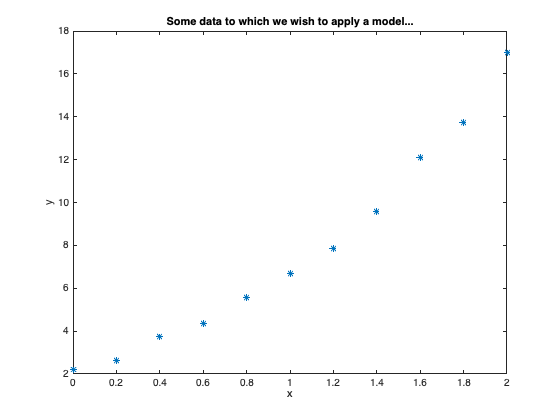

%specify range of values
m0 = [0: 0.01: 10.0];
for j = 1: length(m0)
    yPred = repmat(m0(j), size(x)); %this just creates a vector having m0(j) values (the constant value)
    e2(j) = sum((yData - yPred).^2); %we are computing the sum of squared errors
end

figure(1)
plot(x, yData, '*')
xlabel('x')
ylabel('y')
title('Some data to which we wish to apply a model...')

%find our best fit
figure(2)
plot(m0, e2)
xlabel('m0')
ylabel('square error')
title('graphic least squares solution for mean')

[e2min, k] = min(e2);   % look for minimum
m0Est = m0(k)

m0Est = 7.7700

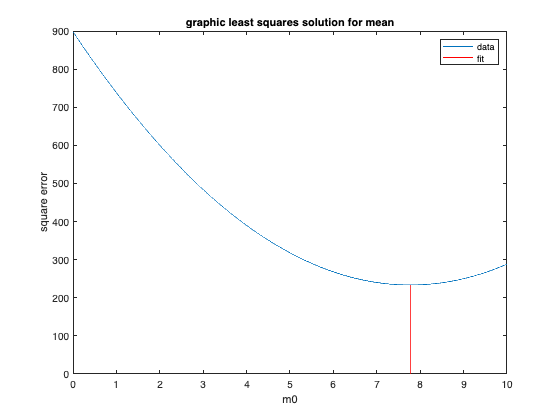

figure(1)
hold on
plot([m0Est m0Est],[0 e2(k)],'r')
legend('data','fit')

Now try looking for the minimum square error using a model that has an intercept and trend (linear fit to data). So, this is a two-parameter model fit! We must search 2d parameter space to find the smallest error...

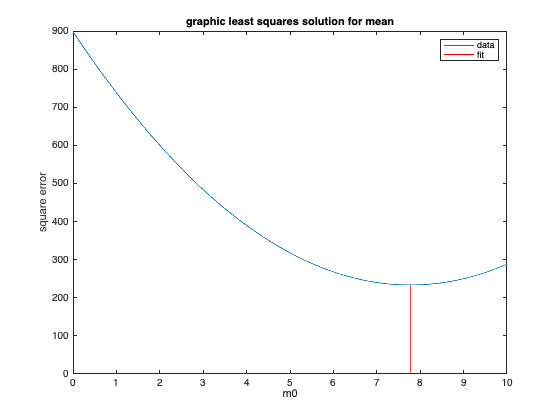

clear e2
m0 = [0: 0.01: 10.0];    
m1 = [0: 0.01: 10.0];

for j = 1: length(m0)
    for k = 1: length(m1)
        yPred = repmat(m0(j), size(x)) + m1(k)*x;
        e2(j, k) = sum((yData - yPred).^2); %compute the square error
    end
end

figure(3); hold off

pcolor(m1, m0, e2); shading flat
xlabel('m1')
ylabel('m0')
title('sum of square error')
colorbar

[val, ind] = min(e2(:));    % find minimum error
[r,c] = ind2sub(size(e2), ind);  % express as row and column
m0Estnew = m0(r)

m0Estnew = 0.6800

m1Est = m1(c)

m1Est = 7.0900

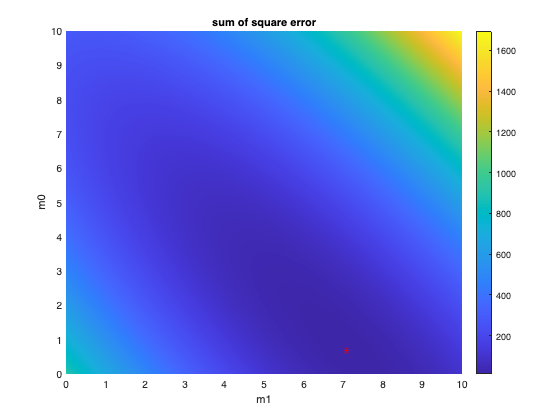

hold on
plot(m1Est, m0Estnew, 'r*')

figure(4); hold off

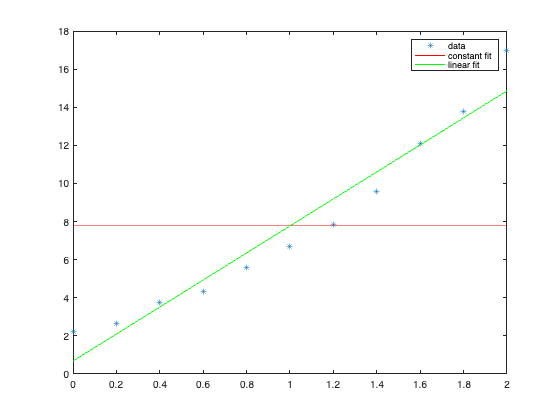

plot(x,yData,'*'); hold on
plot([0 2],[m0Est m0Est],'r') %adds the 'mean value' fit
plot(x,polyval([m1Est m0Estnew],x),'g')
legend('data','constant fit','linear fit')

Note that the same thing could be done for a quadratic fit, or really any other function.  This is tedious and requires us to do a lot of wasted calculations.  It would be much better if we could make a first guess, then intelligently search downslope in error space to find the minimum.  This is exactly what is done on a number of routines including nlinfit in matlab (next method).

## Block 1.5

% METHOD 5 - matlab's nlinfit. This is one of a great many functions in
% matlab that are really 'optimization' functions. What are we trying to
% optimize? Well, we are really trying to minimize the error between the
% data and the model fit.

clear all
close all
clc

intercept = 2.5;
slope = 1;
curvature = 3;
x = [0: 0.2: 2];        % independent data
noiseAmp = 0.4;         % for random number noise
%create the actual data...
yData=polyval([curvature slope intercept],x) + noiseAmp*randn(size(x));

%define the model function. Here I use anonymous function. You can do this
%with a separately saved function file as well.
QUAD=@(C,x) C(1)*x.^2+C(2)*x+C(3) 

QUAD = function_handle with value:
    @(C,x)C(1)*x.^2+C(2)*x+C(3)


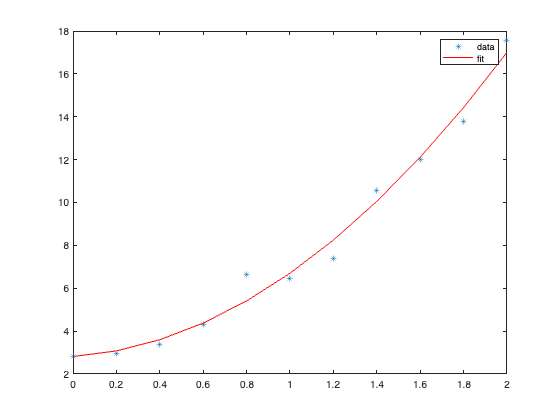

[beta,R,JCOVB,MSE] = nlinfit(x, yData, QUAD, [1 1 1]); %note the need to supply initial guesses

figure(1)
plot(x,yData,'*')
hold on
plot(x,QUAD(beta,x),'r') %add model fit to the plot
legend('data','fit')


% for a pile for functions to do least squares and constrained
% fitting, look at the optim toolbox in matlab (lsqcurvefit or lsqnonlin)